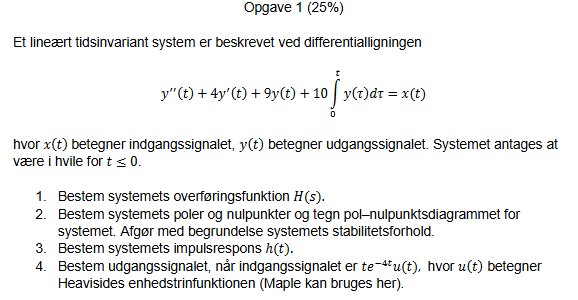

clear all; clc;

### 1. Bestem systemets overføringsfunktion 𝐻(𝑠).

disp('================================================================');
disp('DELOPGAVE 1: BESTEM SYSTEMETS OVERFØRINGSFUNKTION H(s)');
disp('================================================================');
disp(' ');

a = [1, 4, 9, 10];    % Nævner koefficienter: s³ + 4s² + 9s + 10
b = [1, 0];           % Tæller koefficienter: s

[num_tf, den_tf, tf_forklaring] = ElektroMatBibTrinvis.diffLigningTilOverfoeringsfunktionMedForklaring(b, a);

% Vis overføringsfunktionen symbolsk
syms s;
H_s = poly2sym(num_tf, s) / poly2sym(den_tf, s);

disp(' ');
disp('SVAR PÅ DELOPGAVE 1:');
disp('====================');
disp(['H(s) = ' char(H_s)]);
disp(' ');

### 2. Bestem systemets poler og nulpunkter og tegn pol–nulpunktsdiagrammet for systemet. Afgør med begrundelse systemets stabilitetsforhold.

disp('================================================================');
disp('DELOPGAVE 2: POLER, NULPUNKTER OG STABILITET');
disp('================================================================');
disp(' ');

disp('Udfører pol-nulpunktsanalyse med ElektroMatBibTrinvis...');
disp(' ');

[poler, nulpunkter, stabilitet, forklaringsOutput] = ...
    ElektroMatBibTrinvis.polNulpunktsDiagramMedForklaring(b, a, 'Opgave 1: Integro-Differentialsystem');

### 3. Bestem systemets impulsrespons ℎ(𝑡).

disp('================================================================');
disp('           DELOPGAVE 3 - SYSTEMETS IMPULSRESPONS');
disp('================================================================');
disp(' ');

syms t;

[h_t, impuls_forklaring] = ElektroMatBibTrinvis.inversLaplaceMedForklaring(H_s, s, t);

### 4. Bestem udgangssignalet, når indgangssignalet er 𝑡𝑒ି ସ௧ 𝑢(𝑡), hvor 𝑢(𝑡) betegner Heavisides enhedstrinfunktionen (Maple kan bruges her)

disp('================================================================');
disp(' DELOPGAVE 4 - BEREGN UDGANGSSIGNAL y(t)');
disp('================================================================');
disp(' ');

syms s t;

% Definer indgangssignalet som givet i opgaven
x_t = t * exp(-4*t);  % te^(-4t)u(t) - u(t) er implicit

% Lad biblioteket beregne Laplace-transformationen automatisk
[X_s, laplace_forklaring] = ElektroMatBibTrinvis.laplaceMedForklaring(x_t, t, s);

% Nu beregn udgangssignalet
[y_t, udgang_forklaring] = ElektroMatBibTrinvis.beregnUdgangssignalMedForklaring(H_s, X_s, s, t);

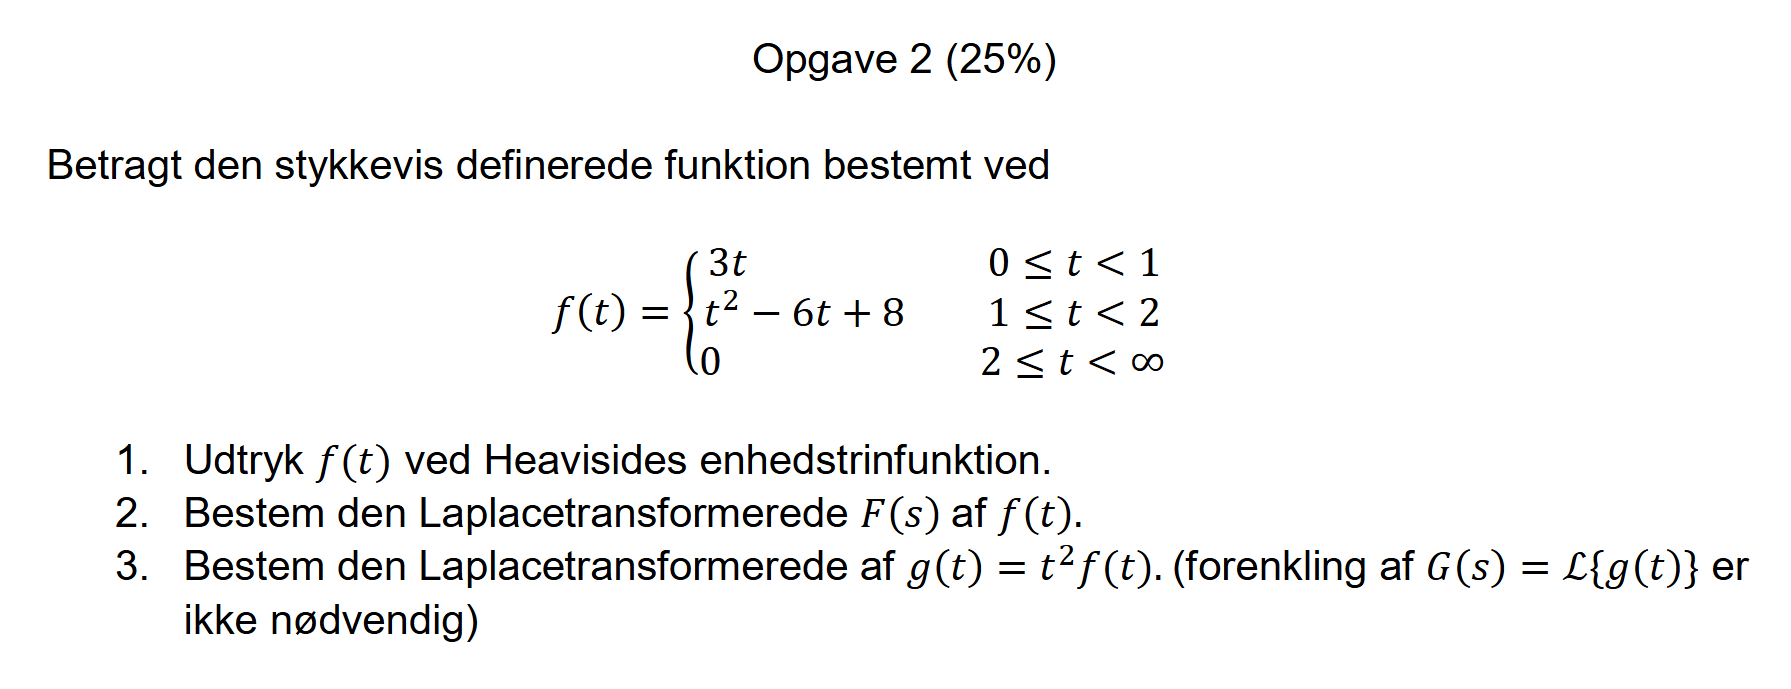

clear all; clc;

### 1. Udtryk 𝑓(𝑡) ved Heavisides enhedstrinfunktion

disp('================================================================');
disp('DELOPGAVE 1: Udtryk 𝑓(𝑡) ved Heavisides enhedstrinfunktion');
disp('================================================================');
disp(' ');

syms t;
func_liste = {3*t, t^2 - 6*t + 8, 0};
graenser = [0, 1, 2, inf];
[f_t, forklaring] = ElektroMatBibTrinvis.stykkevisFunktionMedForklaring(func_liste, graenser, t);

disp(' ');
disp('SVAR PÅ DELOPGAVE 1:');
disp('====================');
disp(['f(t) = ' char(f_t)]);
disp(' ');

### 2. Bestem den Laplacetransformerede 𝐹(𝑠) af 𝑓(𝑡).

disp('================================================================');
disp('DELOPGAVE 2: Bestem den Laplacetransformerede 𝐹(𝑠) af 𝑓(𝑡)');
disp('================================================================');
disp(' ');

syms s;
[F_s, forklaring] = ElektroMatBibTrinvis.laplaceMedForklaring(f_t, t, s);

disp(['F(s) = ' char(F_s)]);

### 3. Bestem den Laplacetransformerede af 𝑔(𝑡) = 𝑡ଶ𝑓(𝑡). (forenkling af 𝐺(𝑠) = ℒ{𝑔(𝑡)} er ikke nødvendig)

disp('================================================================');
disp('DELOPGAVE 3: Bestem den Laplacetransformerede af 𝑔(𝑡) = 𝑡ଶ𝑓(𝑡). (forenkling af 𝐺(𝑠) = ℒ{𝑔(𝑡)} er ikke nødvendig)');
disp('================================================================');
disp(' ');

[G_s, forklaring3] = ElektroMatBibTrinvis.diffLaplaceMedForklaring(F_s, s, 2);

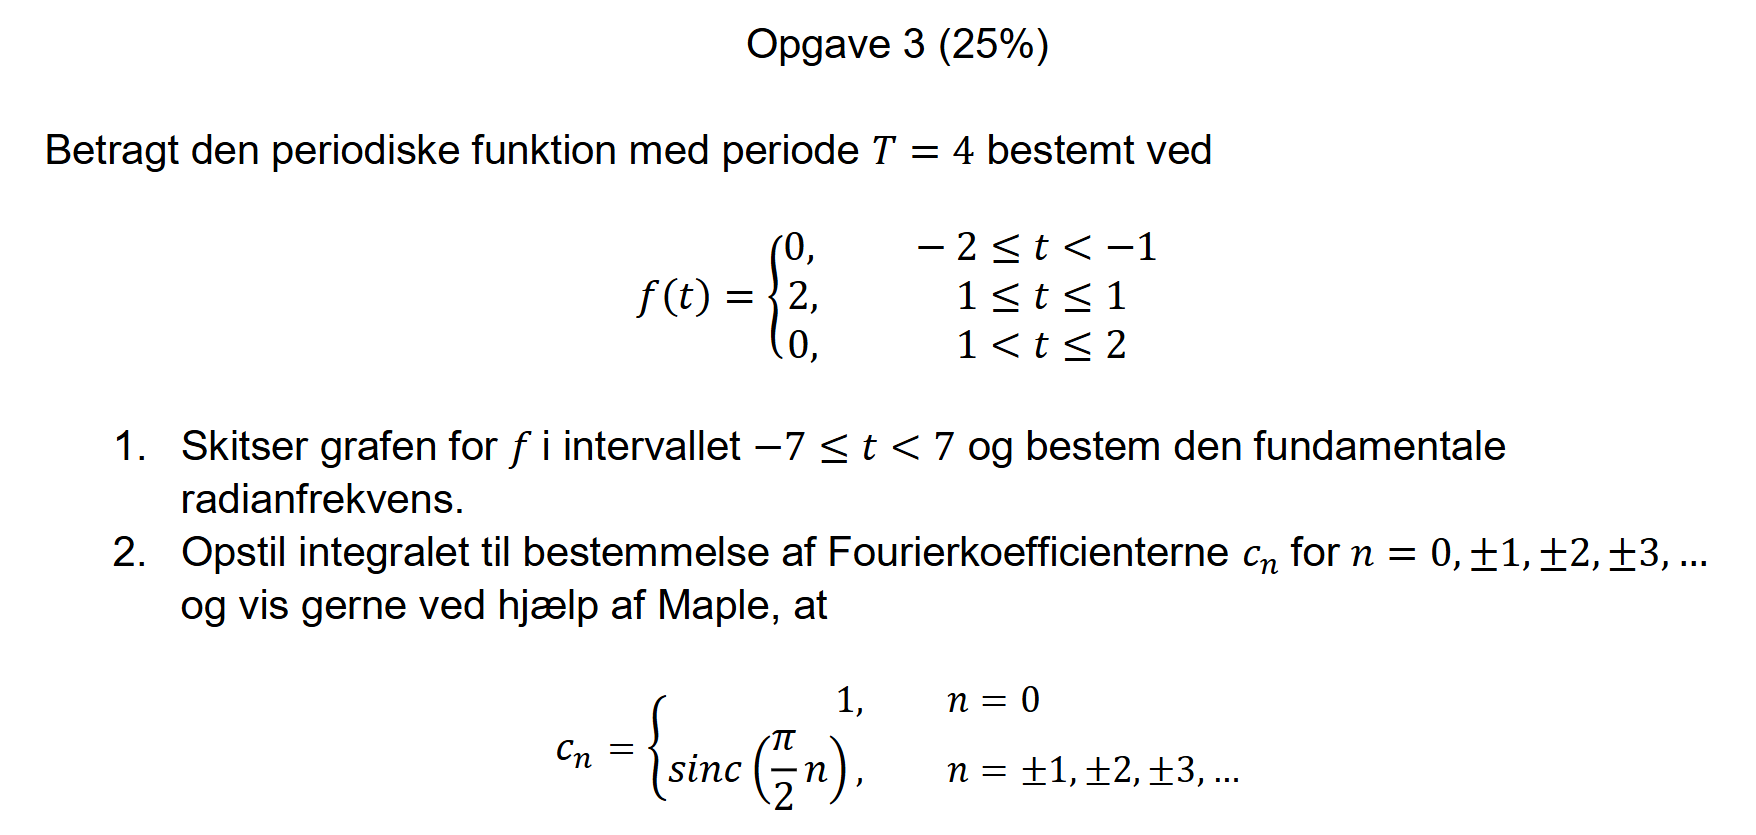

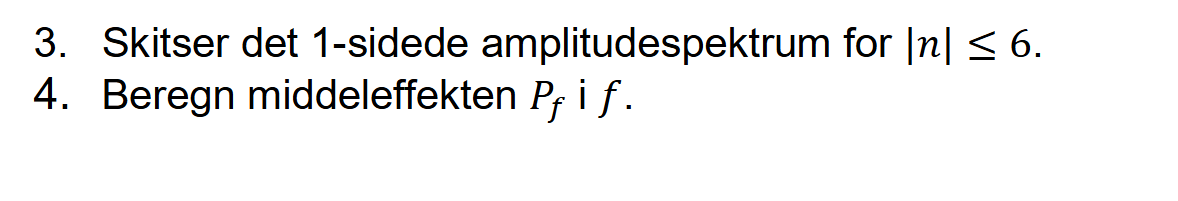

clear all; clc;

### 1. Skitser grafen for 𝑓 i intervallet −7 ≤ 𝑡 < 7 og bestem den fundamentale radianfrekvens. & 2. Opstil integralet til bestemmelse af Fourierkoefficienterne 𝑐௡ for 𝑛 = 0, ±1, ±2, ±3, … og vis gerne ved hjælp af Maple, a

disp('================================================================');
disp('DELOPGAVE 1 & 2: Skitser grafen for 𝑓 i intervallet −7 ≤ 𝑡 < 7 og bestem den fundamentale radianfrekvens.');
disp('================================================================');
disp(' ');

syms t

%% Definer den periodiske funktion
T = 4;  % Periode
f = piecewise(t >= -1 & t <= 1, 2, 0);  % Funktionen

%% DELOPGAVE 1 + 2: Dit bibliotek løser begge automatisk!
disp('Beregner Fourierkoefficienter med trinvis forklaring...');
[cn, forklaring] = ElektroMatBibTrinvis.fourierKoefficienterMedForklaring(f, t, T);
% ↑ Denne ene funktion gør ALT:
% - Beregner ω₀ = 2π/T automatisk
% - Opstiller integralet 
% - Beregner alle cn koefficienter
% - Viser amplitudespektrum

### 3. Skitser det 1-sidede amplitudespektrum for |𝑛| ≤ 6.

disp('================================================================');
disp('DELOPGAVE 3: Skitser det 1-sidede amplitudespektrum for |𝑛| ≤ 6.');
disp('================================================================');
disp(' ');

disp('Rekonstruerer og plotter funktionen...');
[f_approx, plot_forklaring] = ElektroMatBibTrinvis.fourierRaekkeMedForklaring(cn, t, T, 10);
% ↑ Denne funktion:
% - Plotter den periodiske funktion
% - Viser rekonstruktion med Fourierrække

### 4. Beregn middeleffekten 𝑃௙ i 𝑓.

disp('================================================================');
disp('DELOPGAVE 4: Beregn middeleffekten 𝑃௙ i 𝑓.');
disp('================================================================');
disp(' ');

disp('Beregner middeleffekt...');
[P, effekt_forklaring] = ElektroMatBibTrinvis.parsevalTeoremMedForklaring(cn, 6);
% ↑ Denne funktion:
% - Beregner middeleffekten automatisk
% - Viser effektspektrum
% - Giver trinvis forklaring

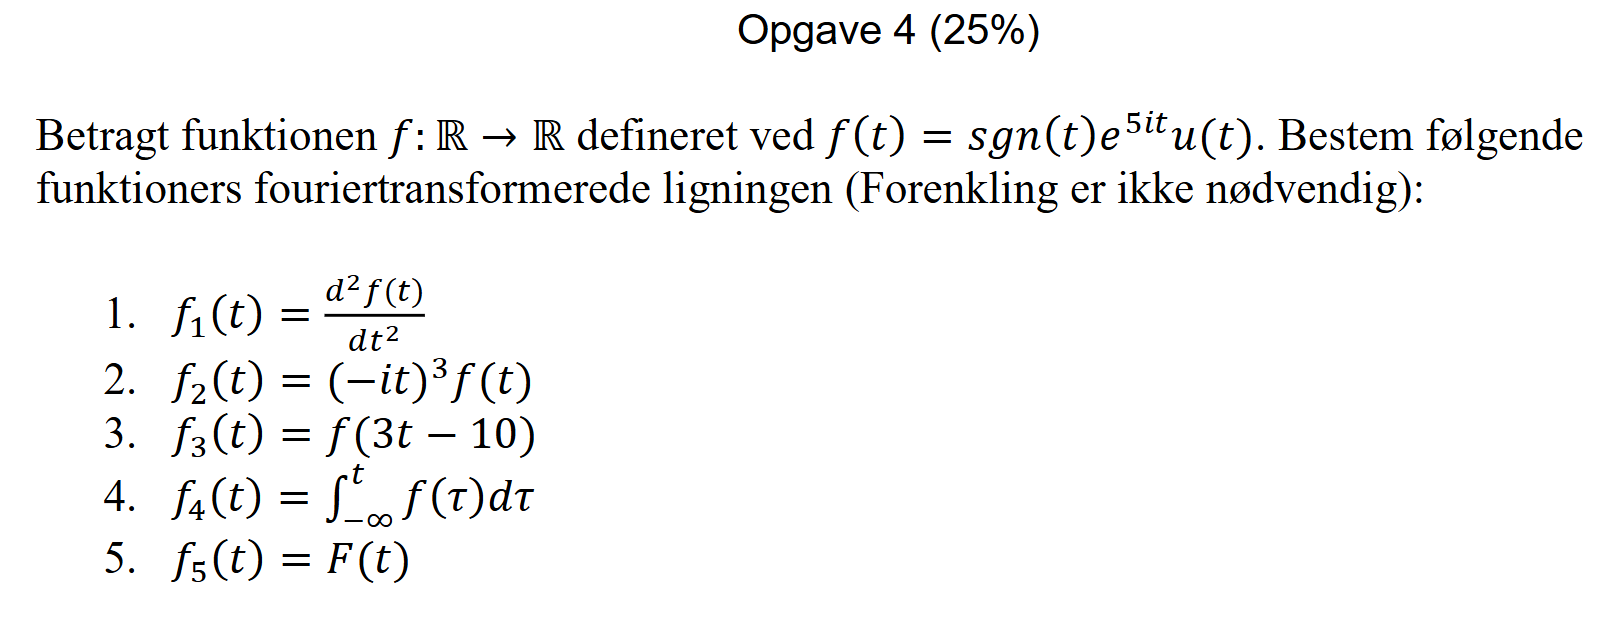

clear all; clc;

syms t omega;

%% Oprindelig funktion f(t) = sgn(t)e^(5it)u(t)
f_original = sign(t) * exp(5*1i*t) * heaviside(t);

### 1. 

disp('=================================================================');

disp('DELOPGAVE 1: f₁(t) = d²f(t)/dt²');

DELOPGAVE 1: f₁(t) = d²f(t)/dt²


disp('=================================================================');

disp(' ');


% Anden afledte
[F1, forklaring1] = ElektroMatBibTrinvis.fourierAfledtMedForklaring(f_original, t, omega, 2);

===== FOURIERTRANSFORMATION AF 2. AFLEDTE =====
 
TRIN 1: Identificer den oprindelige funktion
Vi starter med funktionen, hvis afledte vi skal transformere.
   f(t) = exp(t*5i)*heaviside(t)*sign(t)
 
===== FOURIERTRANSFORMATION =====
 
TRIN 1: Identificer den oprindelige funktion
Vi starter med at identificere den funktion, der skal transformeres.
   f(t) = exp(t*5i)*heaviside(t)*sign(t)
 
TRIN 2: Definér Fouriertransformationen
Fouriertransformationen er defineret som:
   F(ω) = ∫ f(t) · e^(-jωt) dt fra -∞ til ∞
 


TRIN 3: Beregn Fouriertransformationen symbolsk
Vi beregner integralet symbolsk:
   F(ω) = pi*dirac(omega - 5) - 1i/(omega - 5)
 
RESULTAT:
   F(ω) = pi*dirac(omega - 5) - 1i/(omega - 5)
 
===== AFSLUTTET: FOURIERTRANSFORMATION =====
 
TRIN 2: Beregn Fouriertransformationen af f(t)
Først beregner vi Fouriertransformationen af den oprindelige funktion:
   F(ω) = pi*dirac(omega - 5) - 1i/(omega - 5)
 
TRIN 3: Anvend differentieringsreglen
Ifølge egenskaben for Fouriertransformation af afledte:
   F{d^n/dt^n f(t)} = (jω)^n · F{f(t)}
 
TRIN 4: Beregn det endelige resultat
Vi indsætter i formlen:
   F{d^2/dt^2 f(t)} = (jω)^2 · pi*dirac(omega - 5) - 1i/(omega - 5) = (omega^2*1i)/(omega - 5) - 25*pi*dirac(omega - 5)
 
RESULTAT:
   F{d^2/dt^2 f(t)} = (omega^2*1i)/(omega - 5) - 25*pi*dirac(omega - 5)
 
===== AFSLUTTET: FOURIERTRANSFORMATION AF 2. AFLEDTE =====
 


disp(' ');

disp('SVAR PÅ DELOPGAVE 1:');

SVAR PÅ DELOPGAVE 1:


disp('===================');

disp(['F₁(ω) = ' char(F1)]);

F₁(ω) = omega^2*(1i/(omega - 5) - pi*dirac(omega - 5))


disp(' ');

### 2. 

disp('=================================================================');

disp('DELOPGAVE 2: f₂(t) = (-it)³f(t)');

DELOPGAVE 2: f₂(t) = (-it)³f(t)


disp('=================================================================');

disp(' ');


% Tid-multiplikation med (-it)³
[F2, forklaring2] = ElektroMatBibTrinvis.fourierTidMultiplikationMedForklaring(f_original, t, omega, 3, true);

===== FOURIERTRANSFORMATION AF (-JT)^3·F(T) =====
 
TRIN 1: Identificer de oprindelige funktioner
Vi starter med funktionen som multipliceres med en kompleks tidsfaktor.
   f(t) = exp(t*5i)*heaviside(t)*sign(t)\ng(t) = (-jt)^3·f(t)
 
===== FOURIERTRANSFORMATION =====
 
TRIN 1: Identificer den oprindelige funktion
Vi starter med at identificere den funktion, der skal transformeres.
   f(t) = exp(t*5i)*heaviside(t)*sign(t)
 
TRIN 2: Definér Fouriertransformationen
Fouriertransformationen er defineret som:
   F(ω) = ∫ f(t) · e^(-jωt) dt fra -∞ til ∞
 


TRIN 3: Beregn Fouriertransformationen symbolsk
Vi beregner integralet symbolsk:
   F(ω) = pi*dirac(omega - 5) - 1i/(omega - 5)
 
RESULTAT:
   F(ω) = pi*dirac(omega - 5) - 1i/(omega - 5)
 
===== AFSLUTTET: FOURIERTRANSFORMATION =====
 
TRIN 2: Beregn Fouriertransformationen af f(t)
Først beregner vi Fouriertransformationen af den oprindelige funktion:
   F(ω) = pi*dirac(omega - 5) - 1i/(omega - 5)
 
TRIN 3: Anvend tidsmultiplikationsreglen
Ifølge egenskaben for Fouriertransformation af t^n·f(t):
   F{t^n·f(t)} = j^n · d^n/dω^n F(ω)
 
TRIN 4: Beregn den 1. afledte
Vi beregner d/dω F(ω):
   d/dω F(ω) = 1i/(omega - 5)^2 + pi*dirac(1, omega - 5)\nj^1 · d/dω F(ω) = pi*dirac(1, omega - 5)*1i - 1/(omega - 5)^2
 
TRIN 5: Beregn den 2. afledte
Vi beregner d^2/dω^2 F(ω):
   j^2 · d^2/dω^2 F(ω) = 2i/(omega - 5)^3 - pi*dirac(2, omega - 5)
 
TRIN 6: Beregn den 3. afledte
Vi beregner d^3/dω^3 F(ω):
   j^3 · d^3/dω^3 F(ω) = 6/(omega - 5)^4 - pi*dirac(3, omega - 5)*1i
 
TRIN 7: Tilføj kompleks koeffic

disp(' ');

disp('SVAR PÅ DELOPGAVE 2:');

SVAR PÅ DELOPGAVE 2:


disp('===================');

disp(['F₂(ω) = ' char(F2)]);

F₂(ω) = pi*dirac(3, omega - 5)*1i - 6/(omega - 5)^4


disp(' ');

### 3.

disp('=================================================================');

disp('DELOPGAVE 3: f₃(t) = f(3t - 10)');

DELOPGAVE 3: f₃(t) = f(3t - 10)


disp('=================================================================');

disp(' ');


% Skalering og forskydning
[F3, forklaring3] = ElektroMatBibTrinvis.fourierSkaleringMedForklaring(f_original, t, omega, 3, 10);

===== FOURIERTRANSFORMATION AF F(3T-10) =====
 
TRIN 1: Identificer den oprindelige funktion
Vi starter med funktionen, der skal skaleres og forskydes.
   f(t) = exp(t*5i)*heaviside(t)*sign(t)\ng(t) = f(3t-10)
 
===== FOURIERTRANSFORMATION =====
 
TRIN 1: Identificer den oprindelige funktion
Vi starter med at identificere den funktion, der skal transformeres.
   f(t) = exp(t*5i)*heaviside(t)*sign(t)
 
TRIN 2: Definér Fouriertransformationen
Fouriertransformationen er defineret som:
   F(ω) = ∫ f(t) · e^(-jωt) dt fra -∞ til ∞
 


TRIN 3: Beregn Fouriertransformationen symbolsk
Vi beregner integralet symbolsk:
   F(ω) = pi*dirac(omega - 5) - 1i/(omega - 5)
 
RESULTAT:
   F(ω) = pi*dirac(omega - 5) - 1i/(omega - 5)
 
===== AFSLUTTET: FOURIERTRANSFORMATION =====
 
TRIN 2: Beregn Fouriertransformationen af f(t)
Først beregner vi Fouriertransformationen af den oprindelige funktion:
   F(ω) = pi*dirac(omega - 5) - 1i/(omega - 5)
 
TRIN 3: Anvend skaleringsegenskaben
Ifølge skaleringsegenskaben for Fouriertransformation:
   F{f(at)} = (1/|a|) · F(ω/a)
 
TRIN 4: Beregn Fouriertransformationen af skalerede funktion
Vi anvender skaleringsegenskaben:
   F{f(3t)} = (1/3) · F(ω/3) = pi*dirac(omega - 15) - 1i/(3*(omega/3 - 5))
 
TRIN 5: Anvend forskydningsegenskaben
Ifølge forskydningsegenskaben for Fouriertransformation:
   F{f(t-t_0)} = e^(-jωt_0) · F(ω)
 
TRIN 6: Beregn Fouriertransformationen af forskudt funktion
Vi anvender forskydningsegenskaben med t_0 = 10/3:
   F{f(3t-10)} = e^(-jω·3.3333) · -exp(-(omega*10i)/3)*(1i

disp(' ');

disp('SVAR PÅ DELOPGAVE 3:');

SVAR PÅ DELOPGAVE 3:


disp('===================');

disp(['F₃(ω) = ' char(F3)]);

F₃(ω) = -exp(-(omega*10i)/3)*(1i/(3*(omega/3 - 5)) - pi*dirac(omega - 15))


disp(' ');

### 4.

disp('=================================================================');

disp('DELOPGAVE 4: f₄(t) = ∫₋∞ᵗ f(τ)dτ');

DELOPGAVE 4: f₄(t) = ∫₋∞ᵗ f(τ)dτ


disp('=================================================================');

disp(' ');


% Integration
[F4, forklaring4] = ElektroMatBibTrinvis.fourierIntegralMedForklaring(f_original, t, omega);

===== FOURIERTRANSFORMATION AF INTEGRAL =====
 
TRIN 1: Identificer den oprindelige funktion
Vi starter med funktionen, der skal integreres.
   f(t) = exp(t*5i)*heaviside(t)*sign(t)\ng(t) = ∫_{-∞}^{t} f(τ)dτ
 
===== FOURIERTRANSFORMATION =====
 
TRIN 1: Identificer den oprindelige funktion
Vi starter med at identificere den funktion, der skal transformeres.
   f(t) = exp(t*5i)*heaviside(t)*sign(t)
 
TRIN 2: Definér Fouriertransformationen
Fouriertransformationen er defineret som:
   F(ω) = ∫ f(t) · e^(-jωt) dt fra -∞ til ∞
 


TRIN 3: Beregn Fouriertransformationen symbolsk
Vi beregner integralet symbolsk:
   F(ω) = pi*dirac(omega - 5) - 1i/(omega - 5)
 
RESULTAT:
   F(ω) = pi*dirac(omega - 5) - 1i/(omega - 5)
 
===== AFSLUTTET: FOURIERTRANSFORMATION =====
 
TRIN 2: Beregn Fouriertransformationen af f(t)
Først beregner vi Fouriertransformationen af den oprindelige funktion:
   F(ω) = pi*dirac(omega - 5) - 1i/(omega - 5)
 
TRIN 3: Anvend integralreglen
Ifølge egenskaben for Fouriertransformation af integralet:
   F{∫_{-∞}^{t} f(τ)dτ} = F(ω)/(jω) + πF(0)δ(ω)
 
TRIN 4: Beregn F(0)
Vi beregner grænseværdien af F(ω) når ω → 0:
   F(0) = 1i/5
 
TRIN 5: Beregn det endelige resultat
Vi indsætter i formlen:
   F{∫_{-∞}^{t} f(τ)dτ} = pi*dirac(omega - 5) - 1i/(omega - 5)/(jω) + π·1i/5·δ(ω) = (pi*dirac(omega)*1i)/5 + ((1i/(omega - 5) - pi*dirac(omega - 5))*1i)/omega
 
RESULTAT:
   F{∫_{-∞}^{t} f(τ)dτ} = (pi*dirac(omega)*1i)/5 + ((1i/(omega - 5) - pi*dirac(omega - 5))*1i)/omega
 
===== AFSLUTTET: FOURIERTRANSFORMATION AF

disp(' ');

disp('SVAR PÅ DELOPGAVE 4:');

SVAR PÅ DELOPGAVE 4:


disp('===================');

disp(['F₄(ω) = ' char(F4)]);

F₄(ω) = (pi*dirac(omega)*1i)/5 + ((1i/(omega - 5) - pi*dirac(omega - 5))*1i)/omega


disp(' ');

### 5.

disp('=================================================================');

disp('DELOPGAVE 5: f₅(t) = F(t)');

DELOPGAVE 5: f₅(t) = F(t)


disp('=================================================================');

disp(' ');


% Fourier af Fourier
[F5, forklaring5] = ElektroMatBibTrinvis.fourierAfFourierMedForklaring(f_original, t, omega);

===== FOURIERTRANSFORMATION AF F(T) =====
 
TRIN 1: Identificer den oprindelige funktion
Vi starter med funktionen f(t), hvis Fouriertransformerede vi skal transformere.
   f(t) = exp(t*5i)*heaviside(t)*sign(t)
 
===== FOURIERTRANSFORMATION =====
 
TRIN 1: Identificer den oprindelige funktion
Vi starter med at identificere den funktion, der skal transformeres.
   f(t) = exp(t*5i)*heaviside(t)*sign(t)
 
TRIN 2: Definér Fouriertransformationen
Fouriertransformationen er defineret som:
   F(ω) = ∫ f(t) · e^(-jωt) dt fra -∞ til ∞
 


TRIN 3: Beregn Fouriertransformationen symbolsk
Vi beregner integralet symbolsk:
   F(ω) = pi*dirac(omega - 5) - 1i/(omega - 5)
 
RESULTAT:
   F(ω) = pi*dirac(omega - 5) - 1i/(omega - 5)
 
===== AFSLUTTET: FOURIERTRANSFORMATION =====
 
TRIN 2: Beregn Fouriertransformationen af f(t)
Først beregner vi Fouriertransformationen af den oprindelige funktion:
   F(ω) = pi*dirac(omega - 5) - 1i/(omega - 5)
 
TRIN 3: Anvend egenskaben for Fouriertransformation af Fouriertransformationen
Ifølge egenskaben for Fouriertransformation af Fouriertransformationen:
   F{F(t)} = 2π·f(-ω)
 
TRIN 4: Beregn det endelige resultat
Vi indsætter i formlen:
   F{F(t)} = 2π·f(-ω) = 2π·-heaviside(-omega)*exp(-omega*5i)*sign(omega) = -2*pi*heaviside(-omega)*exp(-omega*5i)*sign(omega)
 
RESULTAT:
   F{F(t)} = -2*pi*heaviside(-omega)*exp(-omega*5i)*sign(omega)
 
===== AFSLUTTET: FOURIERTRANSFORMATION AF F(T) =====
 


disp(' ');

disp('SVAR PÅ DELOPGAVE 5:');

SVAR PÅ DELOPGAVE 5:


disp('===================');

disp(['F₅(ω) = ' char(F5)]);

F₅(ω) = -2*pi*heaviside(-omega)*exp(-omega*5i)*sign(omega)


disp(' ');